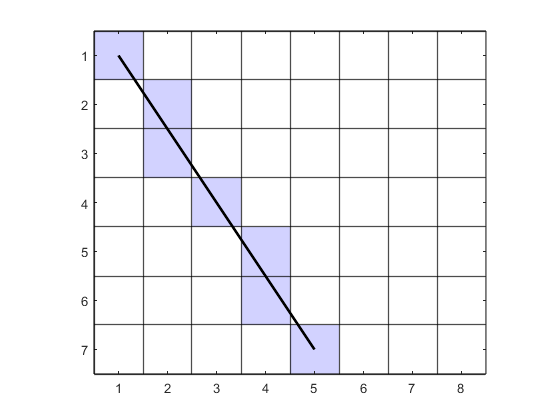

clear

% Line coordinates and colour
x0 = 1;
y0 = 1;
x1 = 5;
y1 = 7;
blue = [210, 210, 255];

% Raster parameters
Nx = 8;
Ny = 7;

% Initialise raster array and calculate pixel co-ordinates
img = uint8(255 * ones(Ny, Nx, 3));

% Draw line
img = drawline(img, x0, y0, x1, y1, blue);

image(img)
hold on
for row = 1 : 1 : Nx
    xline(row-0.5, Color='k', LineWidth=1)
    yline(row-0.5, Color='k', LineWidth=1)
end
plot([x0, x1], [y0, y1], 'k', LineWidth=2)
hold off

xticks(1:Nx)
axis equal
axis([0.5, Nx+0.5, 0.5, Ny+0.5])
exportgraphics(gcf,'../images/bresenham_example_3_1.png','Resolution',300) 

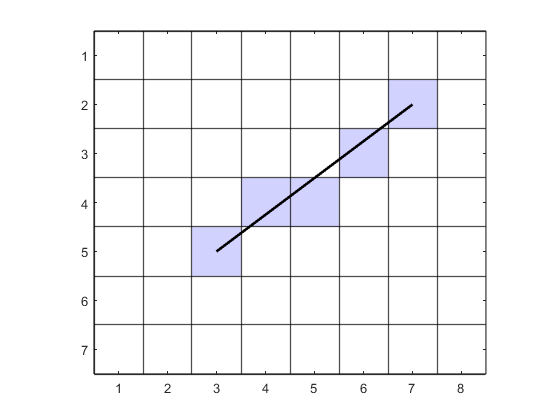

% Line coordinates and colour
x0 = 7;
y0 = 2;
x1 = 3;
y1 = 5;
blue = [210, 210, 255];

% Raster parameters
Nx = 8;
Ny = 7;

% Initialise raster array and calculate pixel co-ordinates
img = uint8(255 * ones(Ny, Nx, 3));

% Draw line
figure()
img = drawline(img, x0, y0, x1, y1, blue);

image(img)
hold on
for row = 1 : 1 : Nx
    xline(row-0.5, Color='k', LineWidth=1)
    yline(row-0.5, Color='k', LineWidth=1)
end
plot([x0, x1], [y0, y1], 'k', LineWidth=2)
hold off

xticks(1:Nx)
axis equal
axis([0.5, Nx+0.5, 0.5, Ny+0.5])
exportgraphics(gcf,'../images/bresenham_example_3_2.png','Resolution',300) 

function R = drawline(R, x0, y0, x1, y1, colour)

x = x0;
y = y0;
dx = abs(x1 - x0);
dy = abs(y1 - y0);
D = dx - dy;
xstep = sign(x1 - x0);
ystep = sign(y1 - y0);

while true
    R(y, x, :) = colour;
    if x == x1 && y == y1
        return
    end
    E = 2 * D;
    if E >= -dy
        x = x + xstep;
        D = D - dy;
    end
    if E <= dx
        y = y + ystep;
        D = D + dx;
    end
end

end
